# S21

## Q1


clear all;
clc;
%      Første model brugt
s = tf('s');

numG =  21*(0.5*s + 1);                        % numerator
denG =  s^2+4*s+21; % denominator

G = numG/denG;


syms a e b f c d f 
G  = c*d;
F1 = f*c

$$F1 = c\,f$$

E1 = (1/a)*e

$$E1 = \frac{e}{a}$$

B1 = b/(1+b*(F1+(1/a)))

$$B1 = \frac{b}{b\,\left(c\,f+\frac{1}{a}\right)+1}$$

sys = a*G*(B1+E1)

$$sys = a\,c\,d\,\left(\frac{e}{a}+\frac{b}{b\,\left(c\,f+\frac{1}{a}\right)+1}\right)$$


simplify(sys)

$$ans = a\,c\,d\,\left(\frac{e}{a}+\frac{b}{b\,\left(c\,f+\frac{1}{a}\right)+1}\right)$$

## Q4

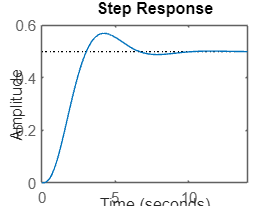

clear all;
clc;
%      Første model brugt
s = tf('s');

numG =  1;                        % numerator
denG =  (s+1)^3; % denominator

G = numG/denG;
K=1;
Gcl = K*G/(1+K*G);
step(Gcl)

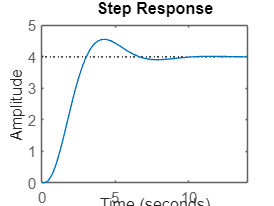

Kt=8;
Gclt = Kt*G/(1+K*G);
step(Gclt)

##  Q12


clear all;
clc;
%      Første model brugt
s = tf('s');

G = 71/(s^2*(s^2+9*s+20))

G =
 
           71
  --------------------
  s^4 + 9 s^3 + 20 s^2
 
Continuous-time transfer function.
Model Properties


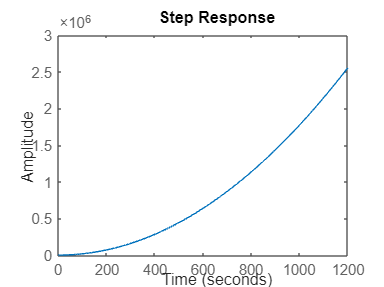


step(G)% viser at systemet ikke er stabilt. 


zero(G) % 


ans =

  0×1 empty double column vector



pole(G) % marginally stable 

ans =          0
         0
   -5.0000
   -4.0000


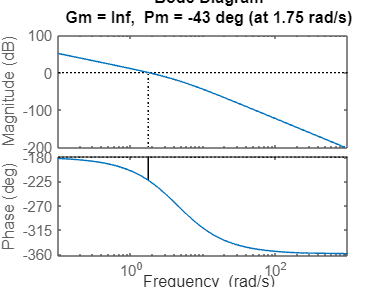

margin(G) % negativ fase 

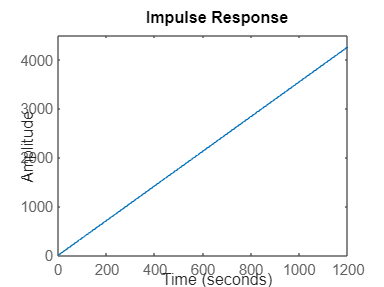

impulse(G)

dcgain(G)

ans = Inf

## Q13

clf;
clear all;
clc;
%      Første model brugt
s = tf('s');

num = s + 1;
den = s^2 + 43*s - 90;
% Kp = 1;
% G = tf(Kp*(num/den));
% 
% for Kp = [100, 0.5, 70, 3, -0.0110, 0,01 ]
%     step(G)
%     hold on
%     legend
% end
% Kp = 1;
G = (s + 1)/(s^2 + 43*s - 90);

% G med unit feedback


P=pole(G) % pol i Højre halplan

P =    -45
     2


Z=zero(G) 

Z = -1


KP=1/0.0111

KP = 90.0901

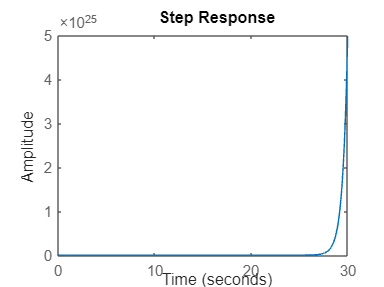


% G med unit feedback
G_uf = (G*KP)/(1+G);
step(G_uf)

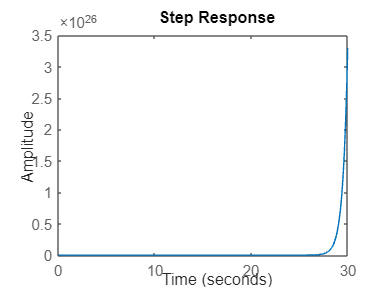

step(G*KP)

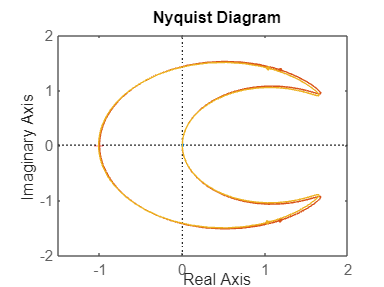

nyquist(G,G*KP,G_uf)


%% så for at får den ud på den anden side 
%lektion 7 slide 17
    % Z = N+P, Hvor N er omgange omkring (-1,0)
    % så vi vil flyttet den ud på den anden side 
    % af -1 så derfor bliver vi nød til at finde den inverse 
    % værdi af skæringen 



% 
% 
% 
% Kp1=100;
% Kp2=0.5;
% Kp3=70;
% Kp4=0.01;
% Kp5=-0.0110;
% 
% G1 = Kp1*(G)/(1+G)
% step(G1)

% 
% legend
% step(minreal(G*Kp1))
% step(G*Kp2)
% step(G*Kp3)
% step(G*Kp4)
% step(G*Kp5)
% grid on

% 
% hold on;
% legend
% step(G1*100)
% step(G2*0.5)
% step(G3*70)
% step(G4*0,01)
% step(G5*(-0.0110))
% grid on
% hold off;



## Q14

clf;
clear all;
clc;
%      Første model brugt
s = tf('s');

num = 1200;
den = s^3 + 54*s^2 + 570*s + 400;

% skal finde fase margin 
 %  skal bruge formlen F-margin=180 + arctan(im/re)

yf = 97.7007

w_c =((-0.991)/(0.134));
 % variable 
yf =180 +  atand(w_c) % Husk korrekt indsæt og at det er "atan"

mag=db2mag(2.5)

mag = 1.3335

## Q15

% denne opgave er bare et SPQ og det er B der er svaret. 


## Q16

clf;
clear all;
clc;
%      Første model brugt
s = tf('s');

numG = 1224;
denG = s^3 + 30*s^2 + 257*s + 612;

G = minreal(numG/denG)

G =
 
             1224
  --------------------------
  s^3 + 30 s^2 + 257 s + 612
 
Continuous-time transfer function.
Model Properties



e = 1/(1+G*2)

e =
 
  s^3 + 30 s^2 + 257 s + 612
  ---------------------------
  s^3 + 30 s^2 + 257 s + 3060
 
Continuous-time transfer function.
Model Properties



o = 612/3060

o = 0.2000


% så fik jeg jo det rigtige svar. 



## Q17

clf;
clear all;
clc;
%      Første model brugt
s = tf('s');

numG = 5*(s+7)*(s+12);
denG = (s+4)*(s+9)*(s+17)*(s+5)*(s+70);

G = minreal(numG/denG)

G =
 
                        5 s^2 + 95 s + 420
  ---------------------------------------------------------------
  s^5 + 105 s^4 + 2857 s^3 + 3.039e04 s^2 + 1.359e05 s + 2.142e05
 
Continuous-time transfer function.
Model Properties


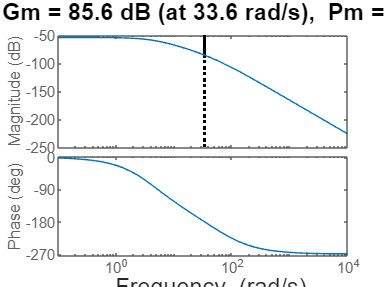

alpha=0.2;
w_c= 15;

[mag,phase] = bode(G,w_c);

Nt_i =3;            %N til at bruge til at flytte vores udgangspunkt i bodeplottet
alphaT = 0.2;       % alpha er lignede KAN IKKE HUSKE HVORFOR!!
gamma_Mt = 70; 

phiT_i = rad2deg(-atan(1/Nt_i));
phiT_m = rad2deg(asin((1 - alphaT)/(1 + alphaT)));
phiT_G = gamma_Mt - 180 - phiT_i - phiT_m;

margin(G)


ti = 3/15;

ti = 0.2000

Taud = 1/(15*sqrt(alpha));

Taud = 0.1491

KpCp=


b_values = [0, 2, -1.5, 0.3, 0.62]
p = atan(3*((1-b)/(1+b*(3^2))))

p = -0.1566

n=3

n = 3

rad2deg(p)

ans = -8.9726

bres=(n - tan(p))/(tan(p)*n^2 + n)

b = 2





Simple måde at solve ligning i Matlab
syms b p n 

eqn = p == atan(n*((1-b)/(1+b*n^2)))

$$eqn = p=-\mathrm{atan}\left(\frac{n\,\left(b-1\right)}{b\,n^{2}+1}\right)$$


eqn = 1.9199 == atan(3*((1-b)/1+b*3^2))

xSol = isolate(eqn, b)

$$xSol = b=\frac{n-\tan\left(p\right)}{\tan\left(p\right)\,n^{2}+n}$$

var = subs(xSol,[b,n,p],[0,0,0])

n=1;

b_values = [0, 2, -1.5, 0.3, 0.62]
b == (n - tan(p))/(tan(p)*n^2 + n)




% 
% Define a range of b values
% b_values = [0, 2, -1.5, 0.3, 0.62]; % Example specific values

% Preallocate array to store results
% results = zeros(size(b_values));
% n=1;

% Loop through each value of b
% for i = 1:length(b_values)
%     b = b_values(i);
%     Calculate the expression
%     result = (n - tan(p))/(tan(p)*n^2 + n)
%     Store the result
%     results(i) = result;
% end


b == (n - tan(p))/(tan(p)*n^2 + n)

% % Display the results
% disp('Results for the expression at different values of b:')
% disp(table(b_values', results', 'VariableNames', {'b', 'Result'}))
% 
% rad2deg(-0.1566)
% 
% w = 15;  % Define frequency range for Bode plot
% [magV , phase] = bode(G,w);
% 
% [M,P] = bode(G,w);            % Get magnitude and phase of G
% M = mag2db(squeeze(M));
% P = squeeze(P);
% maxAngle = max(P)
% Nt_i =3;            %N til at bruge til at flytte vores udgangspunkt i bodeplottet
% alphaT = 0.2;       % alpha er lignede KAN IKKE HUSKE HVORFOR!!
% gamma_Mt = 70;      % Vores umiddelbart ønskede phase Margin        
% 
%                     % Her har vi 
% phiT_i = rad2deg(-atan(1/Nt_i));
% phiT_m = rad2deg(asin((1 - alphaT)/(1 + alphaT)));
% phiT_G = gamma_Mt - 180 - phiT_i - phiT_m;
% 
% deg2rad(110)


clf;
clear all;
clc;

% Define the values for b
b_values = [0, 2, -1.5, 0.3, 0.62];

% Pre-allocate arrays to store results
p_values = zeros(size(b_values));
rad2deg_p_values = zeros(size(b_values));
bres_values = zeros(size(b_values));

% Define the constant n
n = 3;

% Loop through each value of b and compute p, rad2deg(p), and bres
for i = 1:length(b_values)
    b = b_values(i);
    p = atan(3 * ((1 - b) / (1 + b * (3^2))));
    rad2deg_p = rad2deg(p);
    bres = (n - tan(p)) / (tan(p) * n^2 + n);
    
    % Store the results
    p_values(i) = p;
    rad2deg_p_values(i) = rad2deg_p;
    bres_values(i) = bres;
end

% Display the results
disp('b values:');

b values:


disp(b_values);

         0    2.0000   -1.5000    0.3000    0.6200



disp('p values (in radians):');

p values (in radians):


disp(p_values);

    1.2490   -0.1566   -0.5404    0.5162    0.1715



disp('p values (in degrees):');

p values (in degrees):


disp(rad2deg_p_values);

   71.5651   -8.9726  -30.9638   29.5778    9.8291



disp('bres values:');

bres values:


disp(bres_values);

         0    2.0000   -1.5000    0.3000    0.6200



## Q18

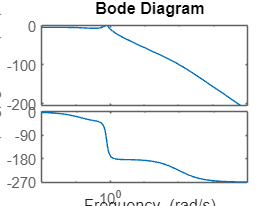

w_c = 10

Ni = 8

clf;
clear all;
clc;
%      Første model brugt
s = tf('s');





w_c = 10 ;      % given crossover frequency
gamma_mt = 45;  % wanted phase margin. 

Ni = 8 % given value for crossover * I-part time constant

%  phase margin = -186 at w_c

numG =  0.7*(s + 0.5);                        % numerator
denG =  (5*s+1)*(s^2 + 0.2*s+0.6)*(0.01*s+1); % denominator


G = numG/denG;  % tr


tau_i = Ni/W_c;  % I - part time constant
tau_d = 1/(W_c*sqrt(alphaT));   % lead part time constant

% following values for alpha and, Kp are indexed in pairs 
% 0.5 and 500 is index 1 and so on.

alpha = [0.5, 2, 0.7, 0.08, 0.07 ]  

alpha =     0.5000    2.0000    0.7000    0.0800    0.0700


Kp    = [500, 1000, 591, 200, -154]

Kp =          500        1000         591         200        -154



TAUi_tf = (tau_i*s+1)/(tau_i*s);
TAUd_tf = (tau_d*s+1)/(alpha*tau_d + 1)

Cz = Kp*TAUd_tf*TAUi_tf;    % PI- Lead kontroller function

% openloop function for the syst and controller 

G_OL = minreal(G*Cz);



% GPT can you write me a script that can calculate the different

Invalid use of operator.

% phase margins for the systems so i can control which value pair
% that gives a phase margin of 45 at the crossover frequency



For alpha = 0.50 and Kp = 500.00:


    Phase Margin = 44.10 degrees at crossover frequency = 11.04 rad/s


    ** This pair gives a phase margin close to 45 degrees. **


For alpha = 2.00 and Kp = 1000.00:


    Phase Margin = 29.01 degrees at crossover frequency = 12.89 rad/s


For alpha = 0.70 and Kp = 591.00:


    Phase Margin = 40.42 degrees at crossover frequency = 11.38 rad/s


For alpha = 0.08 and Kp = 200.00:


    Phase Margin = 60.96 degrees at crossover frequency = 10.09 rad/s


For alpha = 0.07 and Kp = -154.00:


    Phase Margin = -121.27 degrees at crossover frequency = 8.46 rad/s


## Løsnings forslaget.

clear all;
clc;
%      Første model brugt
s = tf('s');

syms oG oi od a



w_c = 10 ;      % given crossover frequency
Ym = 45;  % wanted phase margin. 

Ni = 8 % given value for crossover * I-part time constant

Ni = 8


%  phase margin = -186 at w_c

numG =  0.7*(s + 0.5);                        % numerator
denG =  (5*s+1)*(s^2 + 0.2*s+0.6)*(0.01*s+1); % denominator


G = numG/denG; 
[mag, phase] = bode(G,w_c);
phaseG=phase; % så er phasemargin at 10rad/s

%phase balance eqn, contrubitions from the diff parts
% Ym=  øG + øi + ød -180
% -180 + Ym = oG + oi + od
oi1 = atand(1/Ni); 
% obs på fortegn !!!
od1 = - 180 + Ym - phaseG + oi1;

eqn = asin((1 - a )/(1 + a)) == od;

oSol = isolate(eqn, a)

$$oSol = a=-\frac{\sin\left(\mathrm{od}\right)-1}{\sin\left(\mathrm{od}\right)+1}$$


alpha1 = ((sind(od1)-1)/(sind(od1)+1))

alpha1 = -0.0801


Al = -1*alpha1

Al = 0.0801

% så her har jeg moslet svaret frem på alpha... 
% tau i kan jo også beregnes herfra  - Dette kan gøres ved at at tage N/w
tauI1 = Ni/Al;

tauD1 = (1/(w_c*sqrt(Al)));

   TAUi_tf = (tauI1*s + 1) / (tauI1*s);
   TAUd_tf = (tauD1*s + 1) / (Al*tauD1 + 1);

Gol = minreal(G*TAUd_tf*TAUi_tf);

Kt_P = 1/abs(freqresp(Gol,w_c));
% SSDPASPÅDPÅASDPÅPÅSDPASDPÅ

% Jeg har i hvertfald genskabt resultatet. 



## Q19

% Opave 19 har vi et blok diagram med 2 type nul 
% systemer G1 og G2 dertil har vi K1 og K2 
% når vi åbner ved "A" det får vi et skift tilsvarende 1/K2

% Cues er = 
%           Steady State Error
%           Unit Step Change
%           Open/Closed Loop
%           Step Change


% bode plot viser et DC gain på -7.9588
clear all;
clc;
%      Første model brugt
s = tf('s');

K2 = [118.75, -3.98, -5.97, 91.25, 79.17 ];
DCgain =  -7.9588; % ved w= 1e-05

% RS change 
% Rs = 1/K2;

%Open-loop Gain,
% R(s) Stepchange er = 1/K2, 
%           e1_ss(0) = 0.4
%           e2_ss(0) = 0.05


% type - 0 - e1(0)=0.4 for inputtet R(s) = 1/s 
% Denne er givet ved at 
        % Sjovt nok er de ens at udregne deres e_ss
  %                     e1(0) = 1 / 1 + G1(0)*G2(0)*K2
  %                     e2(0) = 1 / 1 + G1(0)*G2(0)*K2

  % Open Loop hvor e1(0) =  
  %                      0.4 = 1 / 1 + G1(0)*G2(0)*K2
  % Open Loop hvor e2(0) =  
  %                      0.05 = 1 / 1 + G1(0)*G2(0)*K2

syms  g1 g2 k2

eqn1 = 0.4 == 1/(1+ g1*g2*k2)

$$eqn1 = \frac{2}{5}=\frac{1}{g_{1}\,g_{2}\,k_{2}+1}$$

eqn2 = 0.05 == 1/(1+ g1*g2*k2)

$$eqn2 = \frac{1}{20}=\frac{1}{g_{1}\,g_{2}\,k_{2}+1}$$


is1 = isolate(eqn1,k2)

$$is1 = k_{2}=\frac{3}{2\,g_{1}\,g_{2}}$$

is2 = isolate(eqn2,k2)

$$is2 = k_{2}=\frac{19}{g_{1}\,g_{2}}$$

 
ps =
 
Empty sym: 0-by-1
 



% vi antager at sys er = 1 derfor og vi har 2 ligninger

%ASDKAJKLSDKMLASDKML 
% Se løsningsforslag.


## Q20

clear all;
clc;
%      Første model brugt
s = tf('s');

numG =  21*(0.5*s + 1);                        % numerator
denG =  s^2+4*s+21; % denominator

G = numG/denG; 

numD = 1;                        % numerator
denD =  0.01*s+1; % denominator

D = numD/denD; 

gd = minreal(D*G)

gd =
 
         1050 s + 2100
  ----------------------------
  s^3 + 104 s^2 + 421 s + 2100
 
Continuous-time transfer function.
Model Properties


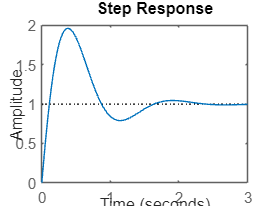


step(G)

Kp=1. 

Kp = 1

frspG = evalfr(G,0)

frspG = 1

frspD = evalfr(D,0)

frspD = 1


F = D*(1/G);

FGD = F*G*D

FGD =
 
                 10.5 s^3 + 63 s^2 + 304.5 s + 441
  ----------------------------------------------------------------
  0.00105 s^5 + 0.2163 s^4 + 11.79 s^3 + 69.13 s^2 + 313.3 s + 441
 
Continuous-time transfer function.
Model Properties


forwardB = -D;

Dcl = (- D + F*G)/(1+Kp*G)

Dcl =
 
  0
 
Static gain.
Model Properties



% du lavede den sgu rigtigt. 
